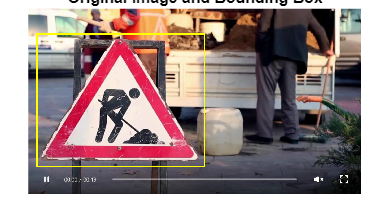

n = 19;

filenameImage = trainingData.imageFilename{n};
I = imread(filenameImage);
bbox = [trainingData.TrafficSign{n}];

% Display the original image and bounding box
annotatedImage = insertShape(I, "rectangle", bbox, "LineWidth", 8);
imshow(annotatedImage)
title('Original Image and Bounding Box')

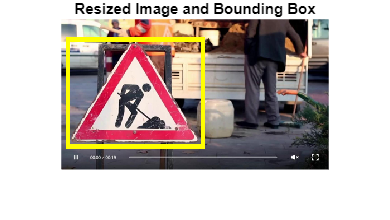


% Resize Image and Bounding Box
scaleFactor = 1/4;
J = imresize(I, scaleFactor);
bboxResized = bboxresize(bbox, scaleFactor);

% Display the resized image and bounding box
annotatedImage = insertShape(J, "rectangle", bboxResized, "LineWidth", 8);
imshow(annotatedImage)
title('Resized Image and Bounding Box')

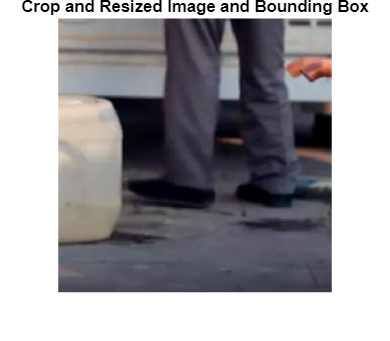


% Crop Image and Bounding Box
cropSize = [512 512]; % Adjust as needed
win = randomWindow2d(size(I), cropSize);
J = imcrop(I, win);
croppedBox = bboxcrop(bbox, win, "OverlapThreshold", 0.9);

targetSize = [512 512]; % Adjust as needed
J = imresize(J, targetSize);
croppedAndResizedBox = bboxresize(croppedBox, targetSize./cropSize);

% Display the cropped and resized image and bounding box
annotatedImage = insertShape(J, "rectangle", croppedAndResizedBox, "LineWidth", 8);
imshow(annotatedImage)
title('Crop and Resized Image and Bounding Box')

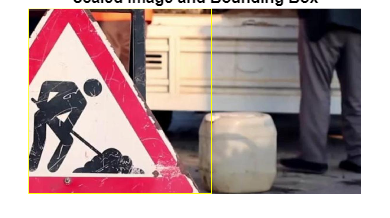


% Warp Image and Bounding Box (Random Scale)
tform = randomAffine2d("Scale", [1.5 1.8]);
rout = affineOutputView(size(I), tform);
J = imwarp(I, tform, "OutputView", rout);
bboxScaled = bboxwarp(bbox, tform, rout, "OverlapThreshold", 0.1);

% Display the scaled image and bounding box
annotatedImage = insertShape(J, "rectangle", bboxScaled, "LineWidth", 8);
imshow(annotatedImage)
title('Scaled Image and Bounding Box')

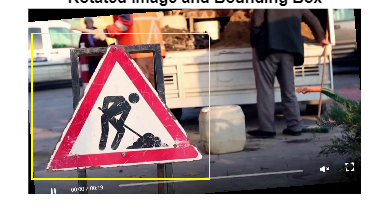


% Warp Image and Bounding Box (Random Rotation)
tform = randomAffine2d("Rotation", [-15 15]);
rout = affineOutputView(size(I), tform);
J = imwarp(I, tform, "OutputView", rout);
bboxRotated = bboxwarp(bbox, tform, rout, "OverlapThreshold", 0.5);

% Display the rotated image and bounding box
annotatedImage = insertShape(J, "rectangle", bboxRotated, "LineWidth", 8);
imshow(annotatedImage)
title('Rotated Image and Bounding Box')